**Taller 11**

# **Invasión Zombie**

Maria Jose Alvarez Duque

**Introducción**

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.

Modelo matemático

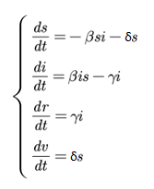

**Supuestos**: población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, *s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad), *i* es el porcentaje de personas infectadas, *r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y *v* es el porcentaje de personas vacunadas.

β es la tasa de transmisión, γ es la tasa de recuperación y aislamiento, y δ es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): 

β = 0.1;

γ = 0.02; 

δ = 0.001; 

s(0) = 0.8; 

i(0) = 0.1; 

r(0) = 0;

v(0) = 0.1;

***Hicimos la verificación y si hay epidemia.***

**Actividades:**

- **Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?**

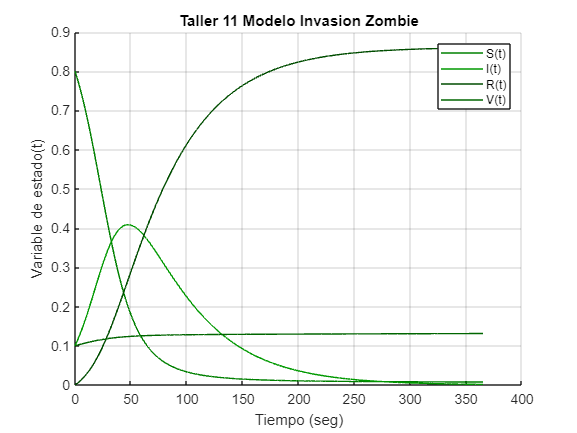

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

eq1 = -beta*s*i-delta*s; % Zombies susceptibles (s)
eq2 = beta*s*i - gamma*i; % Zombies infectados (i)
eq3 = gamma*i; % Zombies recuperados (r)
eq4 = delta*s;

% Usamos el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);

% Tiempo
t0 = 0;
tf = 365;

% Paso
h = 0.1;
t = t0:h:tf;

% Condición inicial 
ci = [0.8 0.1 0 0.1];

% Resolver usando el comando ODE45
[t, sol] = ode45(F, t, ci);

s_sol = sol(:,1); % En una matriz todas las filas de la primera columna
i_sol = sol(:,2);
r_sol = sol(:,3);
v_sol = sol(:,4);

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0];

% Gráfica
figure 
hold on 
plot(t, s_sol, 'Color', colores_verde(1,:))
plot(t, i_sol, 'Color', colores_verde(2,:))
plot(t, r_sol, 'Color', colores_verde(3,:))
plot(t, v_sol, 'Color', colores_verde(4,:))
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
legend('S(t)','I(t)','R(t)','V(t)')
grid on

**Conclusiones **

**Resultados: **

- Observamos que el pico de personas infectadas alcanza hasta un 40% de la población, y notamos que el crecimiento de los infectados junto con el número de vacunados está relacionado con la disminución de las personas susceptibles. Además, se evidencia que la población susceptible disminuye rápidamente y se estabiliza en un punto, mientras que la tasa de vacunación aumenta gradualmente con el tiempo.

**    Analisis:**

- A medida que transcurre el tiempo, se observa que la población susceptible disminuye, ya sea porque se infectan o se vacunan. Esta disminución es casi proporcional al aumento en el número de infectados más el número de vacunados. La curva de vacunados crece despacio porque la vacunación muy baja (0.01), y muestra que solo el 10% de la población se está vacunando.

*Cambiamos las condiciones iniciales para que el pico disminuya un 50% al aumentar la tasa de vacunacion *

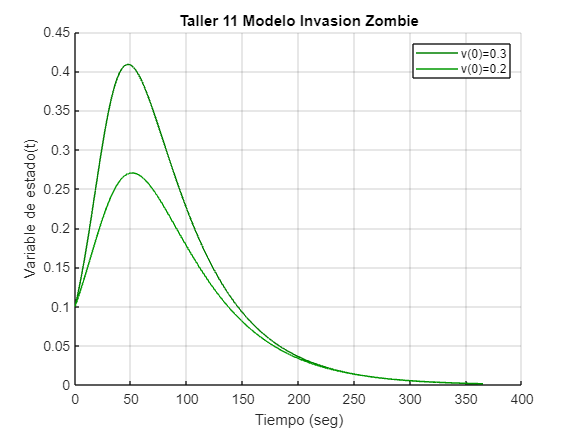

v0 = 0.3;
ci = [0.9-v0 0.1 0 v0];
[t2, sol] = ode45(F, t, ci);
i_sol2 = sol(:,2);

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0];

figure
hold on
plot(t, i_sol, 'Color', colores_verde(1,:))
plot(t2, i_sol2, 'Color', colores_verde(2,:))
xlabel('Tiempo (seg)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on
legend({['v(0)=' num2str(v0)], 'v(0)=0.2'})

**Conclusiones **

**Resultados**:

- Se puede ver que la curva verde oscura alcanza un pico que es casi el doble que el de la curva verde clarita, con valores máximos de 0.41 y 0.27, respectivamente. Además, las dos curvas coinciden y se superponen en el punto x=225.

**Analisis:**

- A medida que aumenta la tasa de vacunación, se observa que disminuye la cantidad de personas infectadas. Aunque las curvas de infección tienen formas diferentes, se nota que el tiempo necesario para la recuperación es similar en ambos casos. También, a medida que incrementamos la tasa de vacunación, el número máximo de personas vacunadas tiende a disminuir.

**2.  Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de *****i*****(0) y usando al menos 5 valores. Observar que al cambiar *****i*****(0) cambia *****s*****(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.**

*Cambiamos condiciones inciales de los infectados zombies cuidando que mantengo en 1 el valor total de las condiciones inciales*

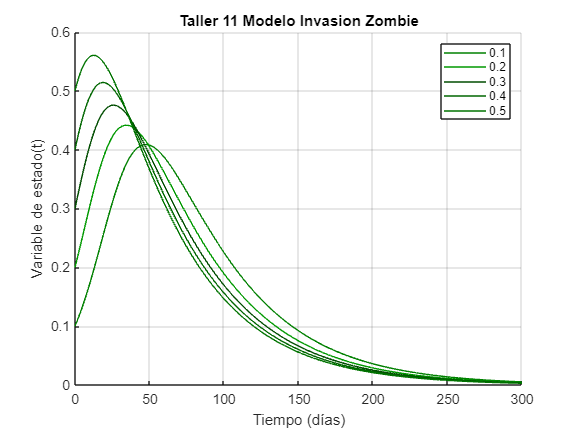

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

eq1 = -beta*s*i-delta*s; % zombies suseptibles (s)
eq2 = beta*s*i - gamma*i; % zombies infectados (i)
eq3 = gamma*i; % zombies recuperados (r)
eq4 = delta*s; % zombies vacunados (v)

% Usamos el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);

% Tiempo
t0 = 0;
tf = 300;

% Paso
h = 0.1;
t = t0:h:tf;

% Condiciones iniciales múltiples
Multipleci = [0.8 0.1 0 0.1 % S I R V
              0.7 0.2 0 0.1
              0.6 0.3 0 0.1
              0.5 0.4 0 0.1
              0.4 0.5 0 0.1];

% Solución numérica
figure
hold on

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0; 0 0.45 0];

for i = 1:size(Multipleci, 1)
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, Multipleci(i,:)); % con todas las variables de la matriz
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', colores_verde(i,:))
end 

legend(num2str(Multipleci(:,2)))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on

**Conclusiones** 

**Resultados**:

- Cada que aumenta el número de personas infectadas, se puede ver un pico más pronunciado en la gráfica. Además, es evidente que a medida que la curva es más grande o el pico es más pronunciado, el tiempo necesario para la recuperación es mayor.

**Analisis**:

- Utilizamos una matriz comparativa para variar las condiciones iniciales de infectados, susceptibles, recuperados y vacunados. Observamos que cuando comenzamos con un valor más alto de personas infectadas (0.5), la curva es más pronunciada, pero también disminuye más rápido, alcanzando su punto mínimo alrededor de x=200, en comparación con otros casos.

**3. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.**

*Cambiamos la tasa de transmision*

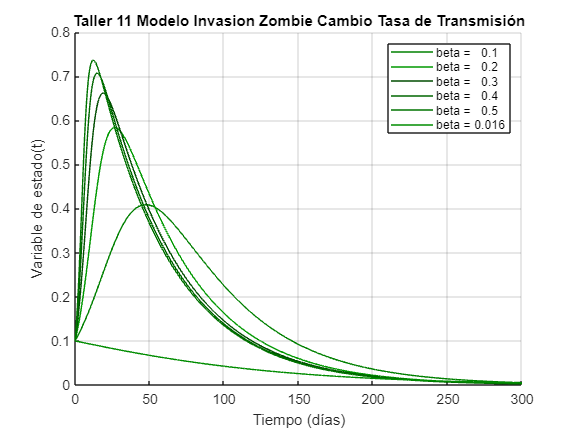

syms s(t) i(t) r(t) v(t)
beta =  [0.1 0.2 0.3 0.4 0.5 0.016];
gamma = 0.02;
delta = 0.001;

% Tiempo
t0 = 0;
tf = 300;

% Paso
h = 0.1;
t = t0:h:tf;

% Condición inicial
ci = [0.8 0.1 0 0.1];

% Solución numérica
figure
hold on

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0; 0 0.45 0; 0 0.55 0];

for j = 1:length(beta)
    eq1 = -beta(j)*s*i-delta*s; % zombies Suseptibles (s)
    eq2 = beta(j)*s*i - gamma*i; % zombies Infectados (i)
    eq3 = gamma*i; % zombies Recuperados (r)
    eq4 = delta*s; % zombies Vacunados (v) 
    
    % Usamos el comando ODE45 para resolver
    F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci);
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', colores_verde(j,:))
end 

legend("beta = " +  num2str(beta'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Transmisión')
grid on

**Conclusiones **

**Resultados**:

- Observamos que cuando el valor de beta aumenta, el pico de la curva también se incrementa. Además, notamos que las curvas más pronunciadas tienden a disminuir y estabilizarse en menos tiempo. También podemos destacar que la curva con al valor 0.016 no presenta ningún pico y en todos los casos, las curvas empiezan en un valor de 0.1.

**Analisis: **

- El valor de 0.016 se obtuvo despejando esta fórmula ( ) y se utilizó en el modelo. Se puede ver que esta curva no muestra un pico, porque su valor inicial es menor que 0.1, el punto de inicio para todas las curvas en el modelo.

**4. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.**

*Cambiamos la Tasa de recuperación*

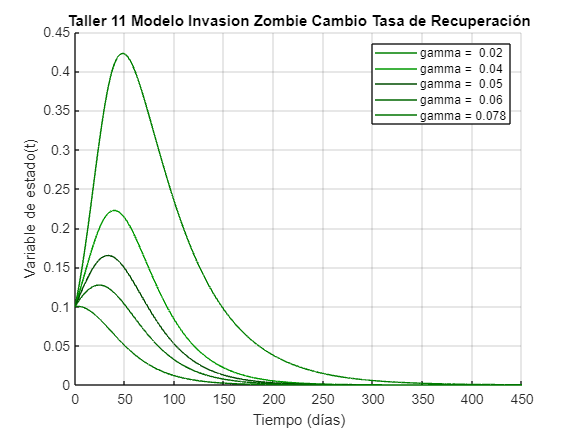

% Tasa de recuperacion
syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = [0.02 0.04 0.05 0.06 0.078];
delta = 0.001;

% Tiempo
t0 = 0;
tf = 450;
h = 0.1;
t = t0:h:tf;

% Condición inicial
ci = [0.8 0.1 0 0.1];

% Solución numérica
figure
hold on

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0; 0 0.45 0];

for idx = 1:length(gamma)
    gamma1 = gamma(idx);
    eq1 = -beta*s*i; % zombies Suseptibles (s)
    eq2 = beta*s*i - gamma1*i; % zombies Infectados (i)
    eq3 = gamma1*i; % zombies Recuperados (r)
    eq4 = delta*s; % zombies Vacunados (v) 
    
    % Usamos el comando ODE45 para resolver
    F = odeFunction([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci);
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', colores_verde(idx,:))
end 

legend("gamma = " +  num2str(gamma'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Conclusiones** 

**Resultados**:

- Para este caso, observamos que cuando el valor de gamma disminuye, el pico de la curva aumenta. También, notamos que las curvas más pronunciadas requieren más tiempo para estabilizarse. Es importante destacar que todas las curvas en la gráfica comienzan en un valor de 0.1.

**Analisis: **

- La curva con el valor de gamma = 0.1 no muestra picos de infección porque la tasa de recuperación es alta. Observamos que a medida que el valor de gamma disminuye, el pico de infección se vuelve más pronunciado, ya que una tasa de recuperación más baja significa más individuos infectados. Para obtener el valor de 0.078, utilizamos la fórmula ()  y despejamos gamma para encontrar este valor.

**5. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.**

*Cambiamos la tasa de reciperación*

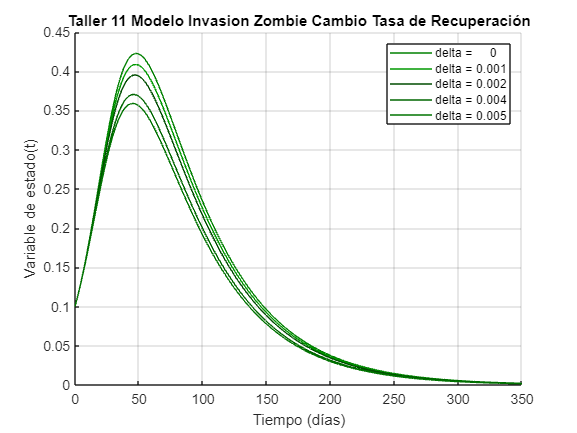

% Definición de variables.
syms s(t) i(t) r(t) v(t)

beta = 0.1; 
gamma = 0.02; 
delta = [0.00, 0.001, 0.002, 0.004, 0.005];

t0 = 0;
tf = 350;
h = 0.1;
t = t0:h:tf;

% Condición inicial.
ci = [0.8 0.1 0 0.1]; 

% Colores de verde.
colores_verde = [0 0.5 0; 0 0.6 0; 0 0.3 0; 0 0.4 0; 0 0.45 0];

% Gráfica
figure
hold on

for idx = 1:length(delta)
    delta1 = delta(idx);
    eq1 = -s*i*beta - delta1*s; % zombies Suseptible (s)
    eq2 = s*i*beta - gamma*i; % zombies Infectados (i)
    eq3 = gamma*i; % zombies Recuperados (r)
    eq4 = delta1*s; % Zombies Vacunados (v) 

    % Usamos el comando ODE45 para resolver
    F = odeFunction([eq1, eq2, eq3, eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci); 

    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', colores_verde(idx,:));
end 

legend("delta = " + num2str(delta'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Resultados**

- Notamos que el valor de delta y el pico de infectados son inversamente proporcionales, lo que significa que a medida que delta disminuye, el pico de infectados tiende a aumentar. Además, es interesante observar que todas las curvas alcanzan una estabilización simultánea alrededor de x=300 en el tiempo.

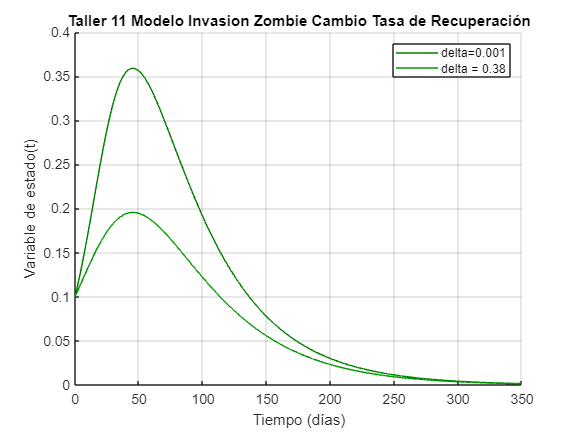

delta1 = 0.38;

% Condición inicial
ci = [0.9-delta1 0.1 0 v0]; 
[t2, sol2] = ode45(F, t, ci); 
i_sol2 = sol2(:,2); 

% Colores de verde
colores_verde = [0 0.5 0; 0 0.6 0];

% Gráfica
figure
hold on
plot(t, i_sol, 'Color', colores_verde(1,:))
plot(t2, i_sol2, 'Color', colores_verde(2,:))
legend('delta=0.001', ['delta = ' num2str(delta1)])
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Conclusiones** 

**Resultados:**

- Todas las curvas en el gráfico comienzan con un valor inicial de y=0.1. Similar a lo observado en el gráfico anterior, notamos que el valor de delta y el pico de infección mantienen una relación inversamente proporcional, lo que indica que a medida que delta disminuye, el pico de infección tiende a aumentar. Es importante mostrar que cuando el valor de delta es 0.38, disminuye un 50% en el pico en comparación con otros escenarios. Además, todas las curvas alcanzan la estabilización simultáneamente alrededor de x=300 en el tiempo.

**Analisis:**

- A medida que aumenta el porcentaje de personas vacunadas, observamos una reducción en el porcentaje de personas infectadas. Esto es porque la tasa de vacunación ayuda a disminuir la propagación de la epidemia de zombies, ya que las personas vacunadas desarrollan inmunidad. Además, para lograr una reducción significativa del 50% en el pico de infectados en comparación con el valor inicial, se debe implementar una tasa de vacunación del 38%.